# Exercise 3: Simulate a Scenario Including a Tuned Controller

In this exercise, we'll use the scenario simulation capabilities explored in exercise 1 to evaluate the performance of a tuned controller to more realistic input signals than unit steps.

## Part 1: Simulate the mission

In this part you will

- Define the mission parameters

- Open and run the simulation

- Show the simulated mission in a Satellite Scenario

- Review results and close windows

### **1) Define the mission parameters**

**Run this section** to define the mission parameters and open the simulation model. These are the same mission parameters as exercise 1, however the model has been updated to include a controller.

% Define mission start and end time
missionstartdate = datetime(2021,1,1,12,0,0);
missionduration = hours(1.5);

% Define the locations we'll need our satellite to point towards
targetNO = [78, 21, 0]; % lat, lon, altitude of Svalbard, NO
targetAmazon = [-4.9, -66, 0]; % lat, lon, altitude of Amazon Rainforest, BR

### 2) Open and run the simulation

**Run this section** to open the model. 

open_system Exercise3

In the Simulink window that opens, **run the model. **

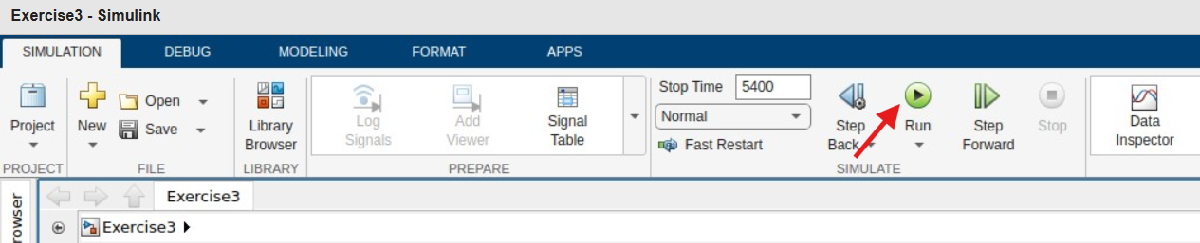

**Open the Data Inspector** to see how our spacecraft rotates over time for this mission. 

# 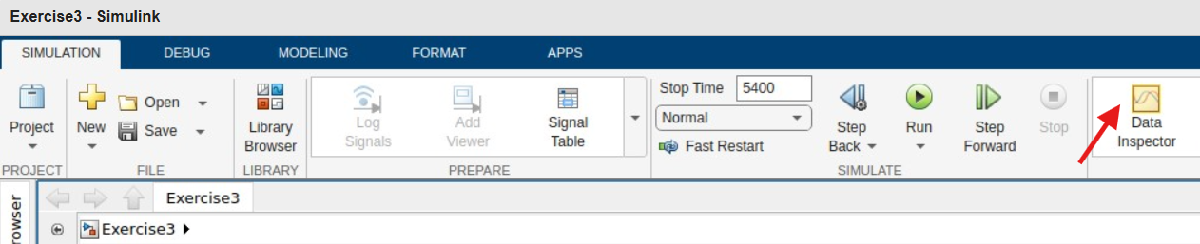

**Adjust the number and arrangement of the displays **in the Data Inspector so there's only 1 display for the spacecraft rotation.

# 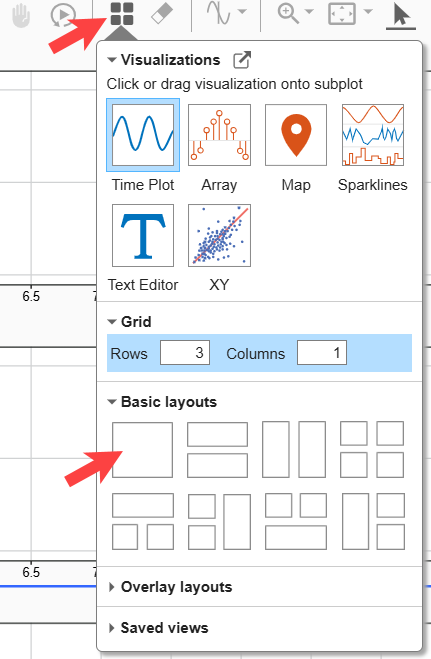

**Plot the actual rotation signals from this exercise against the ideal rotation signals from exercise 1. **You'll notice there's two distinct slews - to and from the Amazon Rainforest location around 2500 seconds, and to and from the Norway ground station around 4000 seconds. You'll notice the actual motion (Exercise 3, shown in orange) from one orientation to another is slower and smoother than the ideal motion (Exercise 1, shown in blue).  

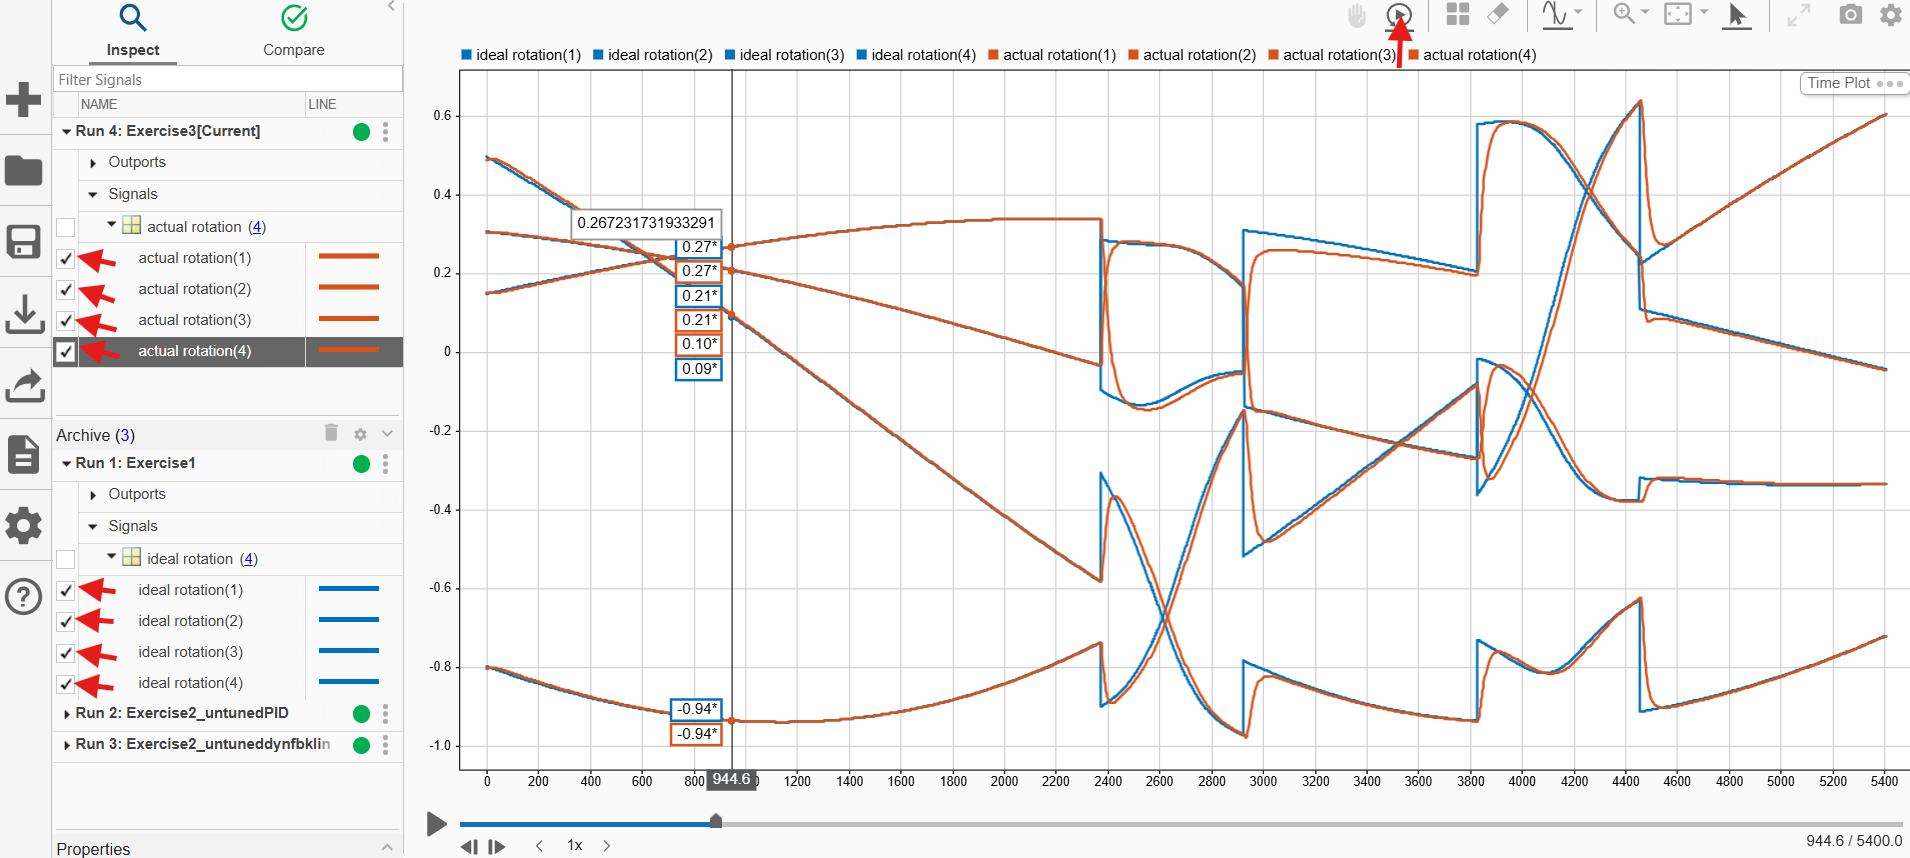

### 3) Show the simulated mission in a Satellite Scenario

Just like in exercise 1, we'll create a higher-fidelity visualization of the mission using a [satellite scenario](https://www.mathworks.com/help/aerotbx/ug/satellitescenario.html) object. 

**Run this section** to see the visualization. For this visualization, we'll use the data from the Simulink model run previously to populate the satellite's attitude and ephemeris. 

% Create scenario
scenario = satelliteScenario(missionstartdate,missionstartdate+missionduration,1);

% Add target points for slews to scenario
gsNO = groundStation(scenario,targetNO(1),targetNO(2),Name="Svalbard, NO");
gsAmazon = groundStation(scenario,targetAmazon(1),targetAmazon(2),Name="Amazon Rainforest");

% Get satellite data from simulation
simulatedSatEphemeris = retime(out.yout{1}.Values,seconds(uniquetol(out.tout, 0.0001)));
simulatedSatAttitude = retime(out.yout{3}.Values,seconds(uniquetol(out.tout, 0.0001)));

% Add satellite to scenario
sat = satellite(scenario,simulatedSatEphemeris,"CoordinateFrame","inertial","Name","Satellite");
pointAt(sat, simulatedSatAttitude, "CoordinateFrame", "inertial", "Format", "quaternion", "ExtrapolationMethod", "fixed");
ac = access(sat,[gsNO gsAmazon]');

% View
viewer = satelliteScenarioViewer(scenario);
sat.Visual3DModel = "SmallSat.glb";
coordinateAxes(sat, Scale=2);
play(scenario,PlaybackSpeedMultiplier=75);
camtarget(viewer,sat);

% Access Line-of-Sight Data
interval = accessIntervals(ac)

While the Satellite Scenario will start to play automatically, keep in mind the controls available to play the scenario at different speeds, forwards or backwards.

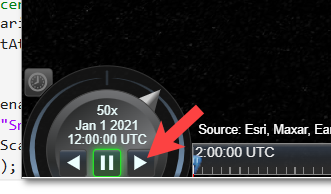

You can also click the Home button to see a full-globe view.